# Daedalus perliminary sizing

clear all; close all; clc;

% define parameters for takeoff
S_TOFL = convlength(8000,"ft","m"); % take of field length (m)
alt_TO = convlength(2500,"ft","m"); % altitude of takoff
Delta_T_TO = convtemp(57,"R","K"); % temp adjustment takeoff - Note a Delta T in degF = R which cna be converted to K. K is equal to a Delta T in degC
C_L_max_TOs = fliplr(linspace(1.3, 2, 5)); % maximum lift coefficient on takeoff (range of conservative vs agressive)

% define parameters for landing
S_FL = convlength(8000,"ft","m"); % landing field length (m) - from spec
W_L2W_TO = .4078; % from vehicle weight sizing 1 (operation pandora)
C_L_max_Ls = fliplr(linspace(2.5, 3.8, 5));  % maximum lift coefficient on landing (range of conservative vs agressive)

% define parameters for drag polars
c_f = .0026; % equivalent parasite area
W_TO = convforce(140000,"lbf","N"); % takeoff weight
A = 7; % aspect ratio
e_clean = .85; % oswald efficiency factor
Delta_C_D_0_flaps_TO = .01; % takeoff flaps - adaptive flaps have low drag
e_TO = .8; % take off flpas
Delta_C_D_0_flaps_L = .055; % landing flaps - adaptive flaps have low drag
e_L = .75; % langing flaps
Delta_C_D_0_gear = .020; % gear down - flying wing has long gear

% define parameters for climb requirements
numEngines = 2; % number of engines
T2W_50F_2_T2W = .8; % turbine thrust decrement due to STP + 50 degF
C_L_max_clean_des = .975; % clean C_L_max at design point
C_L_max_TO_des = 1.3; % C_L_max_TO at design point
C_L_max_L_des = 2.9; % C_L_max_L at design point
W_L_max2W_TO = .83; % max landing weight to take off weight for typical mil. trans. from Roskam part 1 p.107

% define parameters for time to climb requirements
h_cl = convlength(65000,"ft","m");
h_abs = convlength(70000,"ft","m");
t_cl = 3600; % time to climb (s)
climbSteeply = true; % if climb gradiet exceeds 15 degrees

## plot takeoff performance requirements

% compute sigma for takeoff conditions
sigma = DensityRatio(alt_TO, Delta_T_TO); % This density function was validated against tan isa atmo table

% plotting parameters
W2SminPlot = 0;
W2SmaxPlot = 100; 
lbfpft2_2_Npm2 = convlength(convlength(convforce(1,"lbf","N"),"m","ft"),"m","ft"); % convert to SI units
W2SmaxPlot = W2SmaxPlot * lbfpft2_2_Npm2 % convert to SI units

W2SmaxPlot = 4.7880e+03

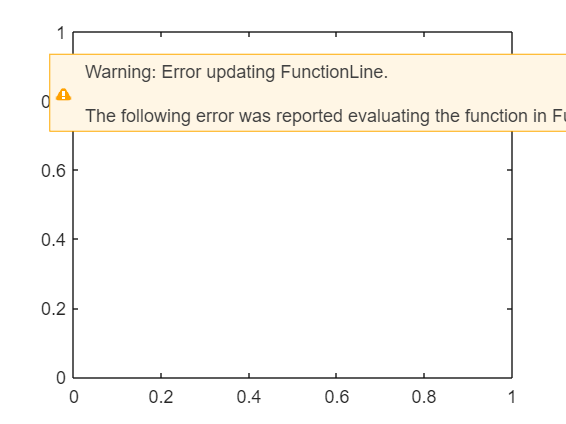


fplot( @(W2S_TO) T2W_Takeoff_FAR25(convlength(8000,"ft","m"), W2S_TO, C_L_max_TO, sigma));

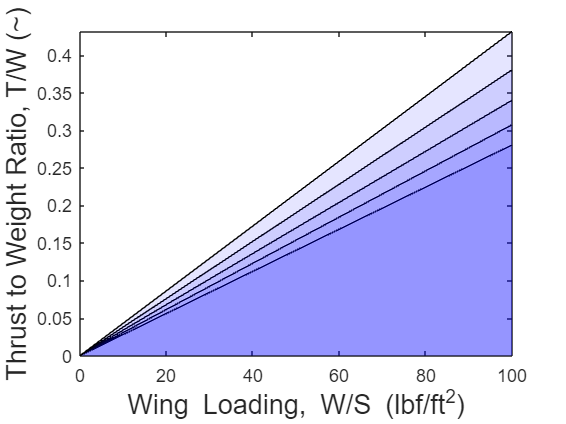


figure;

for C_L_max_TO = C_L_max_TOs
    W2S_TO = linspace(0,W2SmaxPlot,100);
    T2W_TO = T2W_Takeoff_FAR25(S_TOFL, W2S_TO, C_L_max_TO, sigma);
    
    W2S_TO_EngU = W2S_TO / lbfpft2_2_Npm2; % convert to eng U for plotting
    plot(W2S_TO_EngU,T2W_TO);
    hold on;
    area(W2S_TO_EngU,T2W_TO,"FaceAlpha",.10,"FaceColor",[0,0,1]);
    colororder([1,0,0]);
end

xlim([0,max(W2S_TO_EngU)]);
ylim([min(T2W_TO), max(T2W_TO)]);

xlabel("Wing Loading, W/S (lbf/ft^2)", "Interpreter","tex", "FontSize",15);
ylabel("Thrust to Weight Ratio, T/W (~)", "Interpreter","tex", "FontSize",15);

%view([90 -90]);

## Plot landing requirements

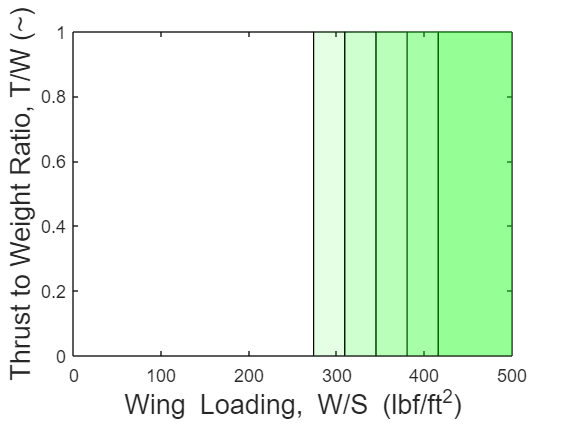

% first lets validate by reproducing Roskam
S_FL_R = convlength(5000,"ft","m");
W_L2W_TO_R = .85;
sigma_R = 1;
C_L_max_L_R = 2.5;
W2S_Landing = W2S_Landing_FAR25(S_FL_R, W_L2W_TO_R, C_L_max_L_R, sigma_R);
W2S_Landing_EngU = W2S_Landing / lbfpft2_2_Npm2; % this checks out

%now lets deal with our stuff
%W2S_Landing = W2S_Landing_FAR25(S_FL, W_L2W_TO, C_L_max_L, sigma);

T2WmaxPlot = 1;
W2SmaxPlot = 500; % ensure this is larger than any contraint or the area will display backwards

figure
for C_L_max_L = C_L_max_Ls
    T2W_L = linspace(0,T2WmaxPlot,100);

    W2S_L = W2S_Landing_FAR25(S_FL, W_L2W_TO, C_L_max_L, sigma);
    W2S_L = ones(size(T2W_L)) * W2S_L;
    
    W2S_L_EngU = W2S_L / lbfpft2_2_Npm2; % convert to eng U for plotting
    plot(W2S_L_EngU,T2W_L);
    hold on;
    
    if(W2SmaxPlot <= W2S_L_EngU(1))
        W2SmaxPlot = W2S_L_EngU(1) + 10;
    end

    area(linspace(W2S_L_EngU(1), W2SmaxPlot), ones([1,100])*T2WmaxPlot, "FaceAlpha",.10, "FaceColor","g", "LineStyle","none")
    colororder([0,0,0]);
end

xlabel("Wing Loading, W/S (lbf/ft^2)", "Interpreter","tex", "FontSize",15);
ylabel("Thrust to Weight Ratio, T/W (~)", "Interpreter","tex", "FontSize",15);

xlim([0, W2SmaxPlot]);
ylim([0,T2WmaxPlot]);

## Drag Polars

% confim my function work use 737-100 compare agains roskam fig 3.21c
m2ft = convlength(1,"m","ft");
f = EquivalentParasiteArea(.003, 6e3/m2ft^2) * m2ft^2;

% we need these for climb sizing
S_wet = WettedArea(W_TO,"Mil. Patrol, Bomb and Transport");
fprintf("Wetted Area = %g ft^2", S_wet * m2ft^2);

Wetted Area = 8466.57 ft^2


f = EquivalentParasiteArea(c_f, S_wet);
fprintf("Equivalent Parasite Area = %g ft^2", f * m2ft^2);

Equivalent Parasite Area = 21.9094 ft^2


% S is chosen as a fist guess estimate and then we would itterate to closure
% because we are a flying wing we will assume wing area S = 1/2 * S_wet
S = 1/2 * S_wet;
C_D_0 = DragCoefficientZeroLift(f,S);
fprintf("C_D_0 = %g", C_D_0);

C_D_0 = 0.00517552

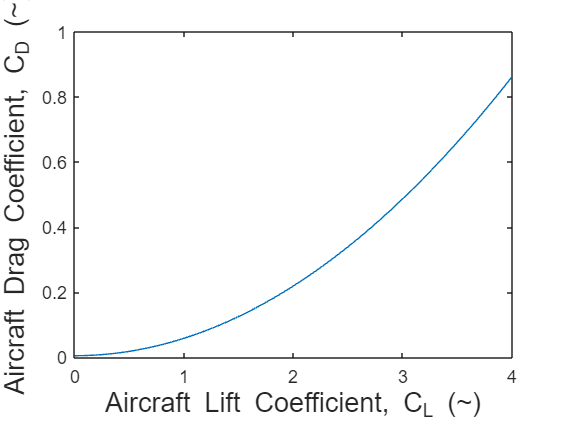


% compute lift and drag values
C_L = linspace(0,4,100);
C_D = DragPolar_parabolic(C_D_0,C_L,A,e_clean);

% plot drag polar clean configuration
figure;
plot(C_L,C_D);
xlabel("Aircraft Lift Coefficient, C_L (~)", "Interpreter","tex", "FontSize",15);
ylabel("Aircraft Drag Coefficient, C_D (~)", "Interpreter","tex", "FontSize",15);


% produce all configurations

%configuation names
Configurations = ["Clean"; "Gear down"; "Takeoff flaps"; "Takeoff flaps w/ gear down"; "Landing flaps"; "Landing flaps w/ gear down"];

%drag coefficents 
C_D_0s = ones(size(Configurations)) * C_D_0; % add clean drag
C_D_0s = C_D_0s + [0;1;0;1;0;1] * Delta_C_D_0_gear; % add gear drag in gear configurations
C_D_0s = C_D_0s + [0;0;1;1;0;0] * Delta_C_D_0_flaps_TO; % add takeoff flaps drag
C_D_0s = C_D_0s + [0;0;0;0;1;1] * Delta_C_D_0_flaps_L; % add landing flpas dragg

% oswald efficiency factors
e = ([1;1;0;0;0;0] * e_clean); % clean oswald efficiencies
e = e + ([0;0;1;1;0;0] * e_TO); % takeoff flaps oswald efficiencies
e = e + ([0;0;0;0;1;1] * e_L); % landing flaps oswald efficiencies

% generate Drag Polars for each configuration
syms C_L; % create symbolic varible C_L for production of drag polars
sympref('FloatingPointOutput',true); % display as decimals (not needed unless debuging)
DragPolars = DragPolar_parabolic(C_D_0s,C_L,A,e); % produce drag polars
DragPolarsString = string(vpa(DragPolars,4)); % convert drag polars to strings with 4 digit decimals

% produce a table of the results
varNames = ["Configuration", "C_D_0", "e", "Drag Polar"]; % table column names
DragSummary = table(Configurations, C_D_0s, e, DragPolarsString, 'VariableNames', varNames) % create table

DragSummary = 6×4 table
           Configuration              C_D_0       e            Drag Polar       
    ____________________________    _________    ____    _______________________

    "Clean"                         0.0051755    0.85    "0.0535*C_L^2 + 0.0052"
    "Gear down"                      0.025176    0.85    "0.0535*C_L^2 + 0.0252"
    "Takeoff flaps"                  0.015176     0.8    "0.0568*C_L^2 + 0.0152"
    "Takeoff flaps w/ gear down"     0.035176     0.8    "0.0568*C_L^2 + 0.0352"
    "Landing flaps"                  0.060176    0.75    "0.0606*C_L^2 + 0.0602"
    "Landing flaps w/ gear down"     0.080176    0.75    "0.0606*C_L^2 + 0.0802"


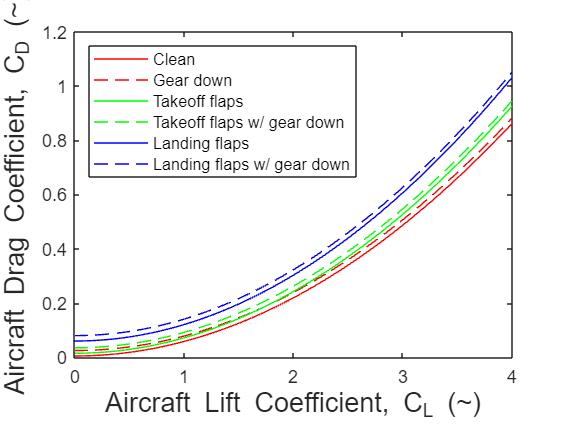

sympref('FloatingPointOutput','default'); % reset diplay prefences

% plot drag polars

% configure plotting parameters
C_LmaxPlot = 4; % maximum C_L to plot
nPointsPlot = 100; % number of points to plot

% produce vlaue to plot
C_Ls = linspace(0,C_LmaxPlot,nPointsPlot); % lift coefficient to plot
C_D = zeros([nPointsPlot, length(DragPolars)]); % initialze drag coefficients
for i = 1:length(C_Ls) % compute drag coefficients
    C_L_num = C_Ls(i);
    C_D(i,:) = subs(DragPolars,C_L,C_L_num);
end

% plot
figure;
colororder([1,0,0; 1,0,0; 0,1,0; 0,1,0; 0,0,1; 0,0,1; 1,1,0; 1,1,0; 1,0,1; 1,0,1; 0,1,1; 0,1,1]);
plot1 = plot(C_Ls,C_D); 
xlabel("Aircraft Lift Coefficient, C_L (~)", "Interpreter","tex", "FontSize",15);
ylabel("Aircraft Drag Coefficient, C_D (~)", "Interpreter","tex", "FontSize",15);
legend(Configurations, Location="northwest");
for i = 1:length(plot1)
    if mod(i,2) == 1;
        style = "-";
    else
        style = "--";
    end
    set(plot1(i),"LineStyle",style);
end

drawnow;
% NOTE: this section often breaks and doesnt draw to fix it just rerun this section (not the whole code) 


## Climb Requirements

% define some required values
W_L_max= W_L_max2W_TO * W_TO;

% %roskam va;ue for debug
% % temporatily define these for debug
% W2S_clean = 100; W2S_TO = 90; W2S_L = 90;
% %temporarily use roskam values
% numEngines = 2;
% W_TO = convforce(125000,"lbf","N"); W_L_max = convforce(115000,"lbf","N");
% C_L_max_clean_des = 1.4; C_L_max_TO_des = 2.0; C_L_max_L_des = 2.8;

nPointsPlot = 100

nPointsPlot = 100

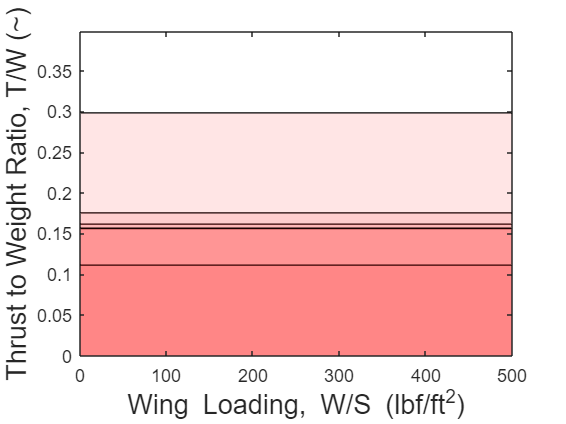

W2SmaxPlot_eU = W2SmaxPlot / lbfpft2_2_Npm2;
W2SminPlot_eU = W2SminPlot / lbfpft2_2_Npm2;

%define plotting parameters
W2S_CL = linspace(W2SminPlot,W2SmaxPlot * lbfpft2_2_Npm2,nPointsPlot);
T2W_CL = zeros([6,nPointsPlot]);

for i = 1:length(W2S_CL)
    % for plotting W/S in eahc configuation doesnt matter
    T2W_CL(:,i) = T2W_Climb_FAR25(numEngines, W2S_CL, W2S_CL, W2S_CL, C_L_max_clean_des, C_L_max_TO_des, C_L_max_L_des, transpose(DragPolars), W_TO, W_L_max, T2W_50F_2_T2W); % compute values
end

% convert units to english for plotting
W2S_CL_EngU = W2S_CL / lbfpft2_2_Npm2; % convert to eng U for plotting

figure;
% plot the sizing lines
for i = 1:6 % itterate through each fo the sizing lines for climb requirements
    plot(W2S_CL_EngU,T2W_CL(i,:));
    area(W2S_CL_EngU,T2W_CL(i,:),"FaceAlpha",.10,"FaceColor",[1,0,0]);
    hold on;
end

T2WmaxPlot = max(T2W_CL,[],"all") + .1;
xlabel("Wing Loading, W/S (lbf/ft^2)", "Interpreter","tex", "FontSize",15);
ylabel("Thrust to Weight Ratio, T/W (~)", "Interpreter","tex", "FontSize",15);

xlim([0, W2SmaxPlot]);
ylim([0,T2WmaxPlot]);

## Time to climb requirement

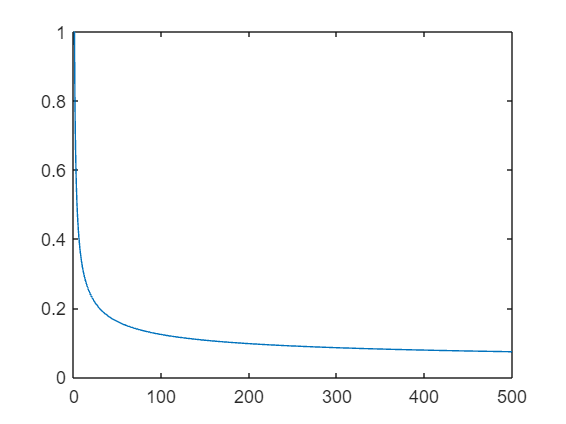

% % validate with roskams values (I validatd this agianst hand calculations- it's good)
% t_cl = 8 * 60; % time to climb (s)
% h_abs = convlength(45000,"ft","m"); h_cl = convlength(40000,"ft","m");
% A = 4; e = .8; C_D_0 = .0096; 
% W2S_T2Cl_expected = 40 * lbfpft2_2_Npm2
% T2W_T2Cl = .629;
% sigma = 1; steepClimb = 1;
% % T2W_TimeToClimb(t_cl, h_cl, h_abs, A, e, C_D_0, W2S_T2Cl, sigma); % this checks out
% W2S_T2Cl = W2S_TimeToClimb(t_cl, h_cl, h_abs, A, e, C_D_0, T2W_T2Cl, sigma, steepClimb)
% % W2S_TimeToClimb currently broken? definetly broken


% climb configuration is clean thus 
Clean_config = DragSummary(strcmp(DragSummary.Configuration, 'Clean'), {'C_D_0','e','Drag Polar'});

% the old way to do it
% plotting parameters
W2S_T2Cl_maxPlot = 500 * lbfpft2_2_Npm2; 
nPointsPlot = 100;
W2S_T2Cls = linspace(0, W2S_T2Cl_maxPlot, nPointsPlot); % wing ploadings
W2S_T2Cls = logspace(0,log10(W2S_T2Cl_maxPlot),nPointsPlot); % this captures the steep region better

T2W_T2Cl = zeros(1, nPointsPlot);

% compute minimum required thrust to weight ratios
for i = 1:nPointsPlot
    W2S_T2Cl = W2S_T2Cls(i);
    T2W_T2Cl(i) = T2W_TimeToClimb(t_cl, h_cl, h_abs, A, Clean_config.e, Clean_config.C_D_0, W2S_T2Cl, sigma, climbSteeply);
end

%remove values where a solution couldnt be found
T2W_T2Cl_filter = T2W_T2Cl > 0; % it will be -1 if no solution could be found
T2W_T2Cl = T2W_T2Cl(T2W_T2Cl_filter);
W2S_T2Cls = W2S_T2Cls(T2W_T2Cl_filter);

W2S_T2Cl_EngU = W2S_T2Cls / lbfpft2_2_Npm2;

% plot the time to climb requirement
figure
plot(W2S_T2Cl_EngU, T2W_T2Cl);

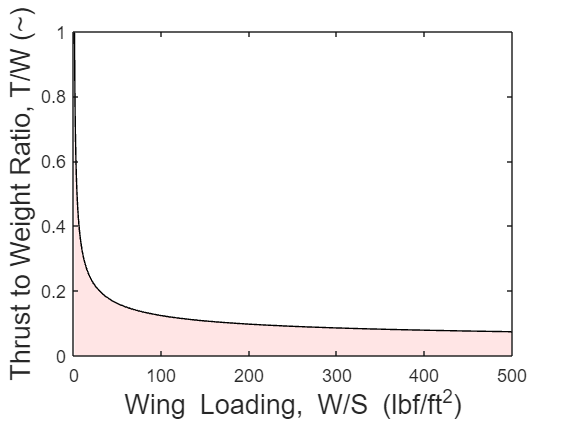

area(W2S_T2Cl_EngU, T2W_T2Cl, "FaceAlpha",.10,"FaceColor",[1,0,0]); 

%formatt figures
xlabel("Wing Loading, W/S (lbf/ft^2)", "Interpreter","tex", "FontSize",15);
ylabel("Thrust to Weight Ratio, T/W (~)", "Interpreter","tex", "FontSize",15);

## Cruise speed sizing

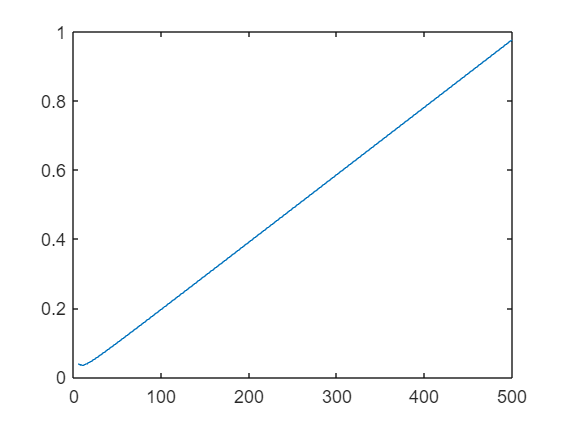

% climb configuration is clean thus 
Clean_config = DragSummary(strcmp(DragSummary.Configuration, 'Clean'), {'C_D_0','e','Drag Polar'});

% assumptions
M_min_cruise = .5; % minimum cruis Mach - from spec
alt_cruise = convlength(65000, "ft", "m"); % cruise altitude (for ferry mission)
k = 1; % weight ratio cruise weight to To weight

[~, a, ~, rho_sl] = atmosisa(0);
V_min_cruise = M_min_cruise .* a;
[~, ~, ~, rho_cruise] = atmosisa(alt_cruise);

sigma_cruise = rho_cruise / rho_sl;

% plotting parameters
W2S_T2Cl_maxPlot = 500 * lbfpft2_2_Npm2; 
nPointsPlot = 100;

W2S_SPDs = linspace(0, W2S_T2Cl_maxPlot, nPointsPlot); % wing ploadings

T2W_SPD = zeros(1, nPointsPlot);

for i = 1:nPointsPlot
    W2S_SPD = W2S_SPDs(i);
    T2W_SPD(i) = T2W_CruiseSpeed(V_min_cruise, A, Clean_config.e, Clean_config.C_D_0, W2S_SPD, k, sigma_cruise);
end

% convert into english units
W2S_SPD_EngU = W2S_SPDs / lbfpft2_2_Npm2;

% plot the time to climb requirement
figure
plot(W2S_SPD_EngU, T2W_SPD);

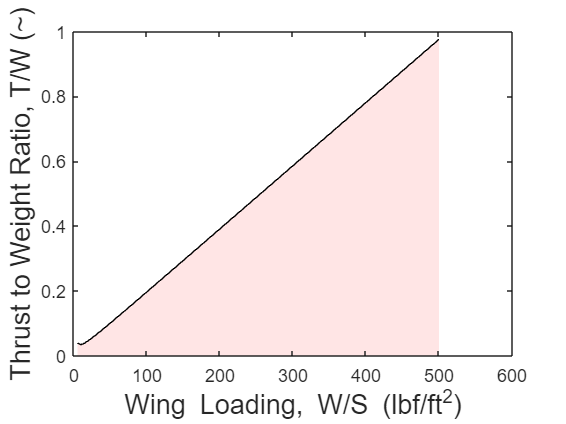

area(W2S_SPD_EngU, T2W_SPD, "FaceAlpha",.10,"FaceColor",[1,0,0]); 

%formatt figures
xlabel("Wing Loading, W/S (lbf/ft^2)", "Interpreter","tex", "FontSize",15);
ylabel("Thrust to Weight Ratio, T/W (~)", "Interpreter","tex", "FontSize",15);

## plot all constraints together

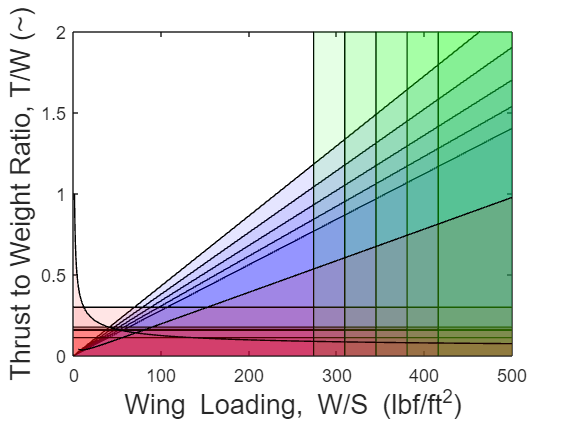

figure;
% plot the sizing lines

% takeoff
%W2SmaxPlot = W2SmaxPlot * Npm2_2_lbfpft2 % convert to SI units
for C_L_max_TO = C_L_max_TOs
    W2S_TO = linspace(0,W2SmaxPlot*lbfpft2_2_Npm2,100);
    T2W_TO = T2W_Takeoff_FAR25(S_TOFL, W2S_TO, C_L_max_TO, sigma);
    
    W2S_TO_EngU = W2S_TO / lbfpft2_2_Npm2; % convert to eng U for plotting
    plot(W2S_TO_EngU,T2W_TO);
    hold on;
    area(W2S_TO_EngU,T2W_TO,"FaceAlpha",.10,"FaceColor",[0,0,1]);
    colororder([1,0,0]);
end

T2WmaxPlot = min(2,max(T2W_TO,[],"all"));


% climb
for i = 1:6 % itterate through each fo the sizing lines for climb requirements
    plot(W2S_CL_EngU,T2W_CL(i,:));
    area(W2S_CL_EngU,T2W_CL(i,:),"FaceAlpha",.10,"FaceColor",[1,0,0]);
    hold on;
end

% landing
for C_L_max_L = C_L_max_Ls
    T2W_L = linspace(0,T2WmaxPlot,100);

    W2S_L = W2S_Landing_FAR25(S_FL, W_L2W_TO, C_L_max_L, sigma);
    W2S_L = ones(size(T2W_L)) * W2S_L;
    
    W2S_L_EngU = W2S_L / lbfpft2_2_Npm2; % convert to eng U for plotting
    plot(W2S_L_EngU,T2W_L);
    hold on;
    
    if(W2SmaxPlot <= W2S_L_EngU(1))
        W2SmaxPlot = W2S_L_EngU(1) + 10;
    end

    area(linspace(W2S_L_EngU(1), W2SmaxPlot), ones([1,100])* T2WmaxPlot, "FaceAlpha",.10, "FaceColor","g", "LineStyle","none")
    colororder([0,0,0]);
end

% time to climb
plot(W2S_T2Cl_EngU, T2W_T2Cl);
area(W2S_T2Cl_EngU, T2W_T2Cl, "FaceAlpha",.10,"FaceColor",[1,0,0]); 

% cruise speed sizing
plot(W2S_SPD_EngU, T2W_SPD);
area(W2S_SPD_EngU, T2W_SPD, "FaceAlpha",.10,"FaceColor",[1,0,0]); 

%formatt figures
xlabel("Wing Loading, W/S (lbf/ft^2)", "Interpreter","tex", "FontSize",15);
ylabel("Thrust to Weight Ratio, T/W (~)", "Interpreter","tex", "FontSize",15);

xlim([0, W2SmaxPlot]);
ylim([0,T2WmaxPlot]);


% choose design point
%plot()"pentagram"
